# CCS 2017b Gyak 3. Frekvenciatartomány

## Egy egyszeru pelda arra, amikor a fazistartalek negativ

s = tf('s');
H = (0.5*s + 1) / (5*s^3 + 4*s^2 + 3*s + 1)


H =
 
         0.5 s + 1
  -----------------------
  5 s^3 + 4 s^2 + 3 s + 1
 
Continuous-time transfer function.



[Gm,Pm,Wgm,Wpm] = margin(H)

Gm = 2.3337

Pm = 38.9464

Wgm = 0.9129

Wpm = 0.7071

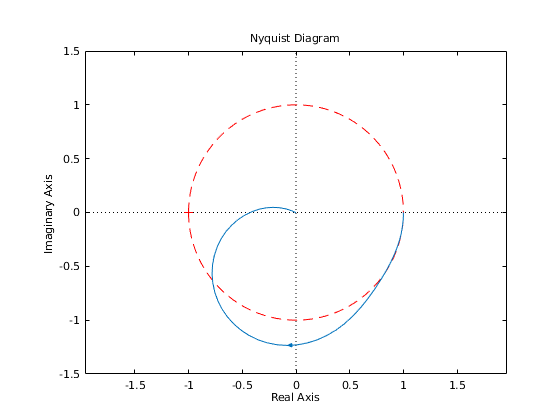

figure, hold on
fplot(@(t) sqrt(1 - t.^2),[-1 1], 'r--')
fplot(@(t) -sqrt(1 - t.^2),[-1 1], 'r--')
Ny_opts = nyquistoptions;
Ny_opts.ShowFullContour = 'off';
Ny_opts.Grid = 'off';
Ny_opts.MagUnits = 'abs';
nyquistplot(H, Ny_opts), axis equal

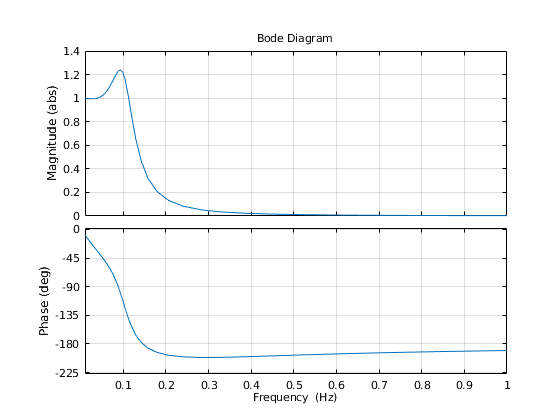

figure, hold on
Bd_opts = bodeoptions;
Bd_opts.FreqUnits = 'Hz';
Bd_opts.FreqScale = 'linear';
Bd_opts.MagUnits = 'abs';
bodeplot(H,Bd_opts), grid on
xlim([0.01,1])

## Visszacsatolt zárt hurok 

H_cls = feedback(H,1);
[Poles, Zeros] = pzmap(H_cls)

Poles =   -0.0705 + 0.7759i
  -0.0705 - 0.7759i
  -0.6589 + 0.0000i

Zeros = -2

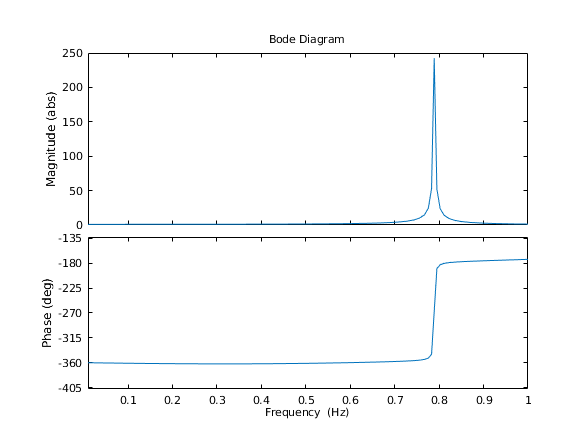

figure('Position', [ 211 81 583 437 ], 'Color', [1 1 1])
bodeplot(H_cls, Bd_opts)
xlim([0.01,1])